clear
rng(203829)
addpath('functions') % Make sure your functions F_ct, dF_ct, G_ct are accessible
set(groot, 'defaultTextInterpreter', 'latex');
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
plotPos = [100 100 800, 400];
% plotPos2 = [100 100 800, 600];
plotPos2 = [143.87,73.93,851.725,540.345];


rng(203829)

% System Parameters
% Define parameters once here or use persistent inside functions
% Using persistent inside functions is generally cleaner.
kappa = 5*10^-5;
lambda = 3;
Lambda = 5*10^-5;
beta = 0.0065;
H = 0.05;

n_states = 3; % Number of states [x1, x2, x3]
n_inputs = 1; % Number of inputs [u]

% Process Noise Covariance
Rv = diag([1, 1, 10^-8]);

% Measurement Noise Covariance (for EKF)
Re = diag([0.1, 0.1]);
n_outputs = size(Re, 1); % Number of outputs for EKF measurements

% Output matrix C (for EKF measurements)
C = [1, 0, 0; % Measure x1 (neutron concentration) 
     0, 1, 0]; % Measure x2 (delayed neutron precursor concentration)

% Output matrix Co (for Controller - tracking x1 only)
Co = [1,0,0];
n_outputs_c = size(Co, 1); % Number of outputs for MPC control (should be 1)


dt = 10^-3;   % Simulation/Euler time step

% Continuous-time system functions
% Function defining the state derivatives dx/dt = F_ct(x) + G_ct(x)u
% Using persistent variables to avoid repeated definition overhead
function dxdt = F_ct(~,x0) % t is ignored
    persistent kappa lambda Lambda beta H;
    if isempty(kappa)
       kappa = 5e-5; lambda = 3; Lambda = 5e-5; beta = 0.0065; H = 0.05;
    end
    dxdt = [
       (x0(3) - beta)/Lambda * x0(1) + lambda * x0(2);
       beta/Lambda * x0(1) - lambda * x0(2);
       -kappa*H*x0(1);
    ];
end

function res = F_ct_dae(t, y, yp)
    persistent kappa lambda Lambda beta H;
    if isempty(kappa)
       kappa = 5e-5; lambda = 3; Lambda = 5e-5; beta = 0.0065; H = 0.05;
    end

    f = [
       (y(3) - beta)/Lambda * y(1) + lambda * y(2);
       beta/Lambda * y(1) - lambda * y(2);
       -kappa*H*y(1);
    ];

    res = yp - f;
end

% Jacobian of F_ct w.r.t x (d(F_ct)/dx)
function JF = dF_ct(x0)
    persistent kappa lambda Lambda beta H;
    if isempty(kappa)
       kappa = 5e-5; lambda = 3; Lambda = 5e-5; beta = 0.0065; H = 0.05;
    end
    JF = [
       (x0(3) - beta)/Lambda,  lambda, x0(1)/Lambda;
       beta/Lambda, - lambda, 0;
       -kappa*H, 0, 0;
    ];
end

% Function defining the input mapping G_ct(x)
function B_ct = G_ct(x0)
    persistent Lambda;
    if isempty(Lambda)
       Lambda = 5e-5;
    end
    B_ct = [
       x0(1)/Lambda;
       0;
       0;
    ];
end

% Jacobian of G_ct w.r.t x (d(G_ct)/dx)
function JG_dx = dG_ct_dx(x0)
    persistent Lambda;
    if isempty(Lambda)
       Lambda = 5e-5;
    end

    JG_dx = [
        1/Lambda, 0, 0;
        0, 0, 0;
        0, 0, 0;
    ];
end


% Discrete-time approximate nominal system function (Euler step at Ts_sim)
% x_{k+1} = f_d(x_k, u_k, Ts_sim)
function x_next = f_d(x0, u, Ts_sim)
    % Use persistent parameters
    persistent kappa lambda Lambda beta H;
    if isempty(kappa)
       kappa = 5e-5; lambda = 3; Lambda = 5e-5; beta = 0.0065; H = 0.05;
    end
    % Inlined F_ct and G_ct for speed, using persistent parameters
    f_val = [
       (x0(3) - beta)/Lambda * x0(1) + lambda * x0(2);
       beta/Lambda * x0(1) - lambda * x0(2);
       -kappa*H*x0(1);
    ];
    g_val = [
       x0(1)/Lambda;
       0;
       0;
    ];

    x_next = x0 + f_val * Ts_sim + g_val * u * Ts_sim;
end

% Discrete-time approximate unforced system function (Euler step at Ts_sim)
% z_{k+1} = f_approx_unforced(z_k, Ts_sim)
function z_next = f_approx_unforced(z0, Ts_sim)
    % Use persistent parameters
    persistent kappa lambda Lambda beta H;
    if isempty(kappa)
       kappa = 5e-5; lambda = 3; Lambda = 5e-5; beta = 0.0065; H = 0.05;
    end
     % Inlined F_ct for speed, using persistent parameters
     f_val = [
       (z0(3) - beta)/Lambda * z0(1) + lambda * z0(2);
       beta/Lambda * z0(1) - lambda * z0(2);
       -kappa*H*z0(1);
    ];
    z_next = z0 + f_val * Ts_sim;
end



% Simulation Parameters
x0 = [1000, 0, beta]'; % Initial state
% x0 = [1050, 5, beta+0.0001]'; % Different initial state for EKF test

Tfinal = 4;         % total simulation time [s]
Ts_sim = dt;        % Simulation sampling time
N_sim = round(Tfinal / Ts_sim); % number of simulation steps

% Controller Parameters
Tc = 0.005; % Controller time step [s] (Example: 5 ms)
M = round(Tc / Ts_sim); % Number of simulation steps per controller step
if abs(M * Ts_sim - Tc) > 1e-9
    error('Controller timestep Tc must be a multiple of simulation timestep dt');
end
Np = 20; % Prediction horizon (in controller steps)
Nc = Np; % Control horizon (usually Nc <= Np)

% Tuning parameters
Q_y = eye(Np * n_outputs_c); % Output weighting matrix for ||Y_N - Y_ref_N||_{Q_y}^2
Q_u = 10^-3 * eye(Nc * n_inputs); % Control input weighting matrix for ||U_N||_{Q_u}^2


% Reference Trajectory (step change for output 1, hold initial for output 2)
% Reference is for the controlled output (y_c = Co * x)
y_ref_sim = x0(1)*ones(n_outputs_c, N_sim + 1); % Size 1 x (N_sim+1)

step_time = 1;
step_sim_idx = round(step_time / Ts_sim);
% Step change for output 1 at step_time
y_ref_sim(step_sim_idx:end) = x0(1) * 2;

y_ref_sim = 1.5 * x0(1) - x0(1)/2 * square(2*pi*(2/(N_sim))*(1:N_sim+1), 50); 


% Data storage
x_sim     = [x0, zeros(n_states, N_sim)];   % true state
y_sim     = zeros(n_outputs, N_sim + 1);     % measurements (y(t) corresponds to x(:,t))
u_sim     = zeros(n_inputs, N_sim);         % control inputs (applied at each sim step)
z_sim     = [x0, zeros(n_states, N_sim)];   % Unforced trajectory storage (for plotting open loop z)

% EKF Data storage
xhat_sim  = zeros(n_states, round(N_sim/M) + 1);   % Estimated state (at Tc steps)
P_sim     = zeros(n_states, n_states, round(N_sim/M) + 1); % Covariance matrix (at Tc steps)

% EKF Initialization
xhat_sim(:, 1) = x0; % Initialize EKF estimate with true state (as requested)
% xhat_sim(:, 1) = [1050, 5, beta+0.0001]'; % Example of a different initial estimate
P0 = eye(n_states) * 1e-6; % Small initial covariance if initial state is known well
% P0 = diag([1e-6, 1e-6, 1]); % Larger initial covariance if initial state has uncertainty
P_sim(:, :, 1) = P0;


% Initial output measurement (with noise)
e0 = mvnrnd(zeros(n_outputs, 1), Re)';
y_sim(:, 1) = C * x_sim(:, 1) + e0;

% Initial unforced state for plotting z_sim (at dt resolution)
z_sim(:,1) = x_sim(:,1);


current_u = zeros(n_inputs, 1); % Variable to hold the control input constant over Tc

% Pre-allocate storage for timing data
N_ctrl_steps = round(N_sim/M);
time_log = zeros(1, N_ctrl_steps);
time_stamps_ctrl = (0:(N_ctrl_steps-1)) * Tc;


% Simulation loop (runs at dt)
for t_sim_step = 1:N_sim
    
    % Check if it's the start of a new controller/EKF interval (every Tc)
    if mod(t_sim_step - 1, M) == 0
        tic; % Start timer for this control interval calculation

        % t_kf_step and t_ctrl_step are the same index for the Tc-based arrays
        if t_sim_step == 1
            t_kf_ctrl_step = 1;
        else
            t_kf_ctrl_step = (t_sim_step - 1) / M + 1;
        end

        % --- Extended Kalman Filter (EKF) - Runs at Tc ---
        % Uses measurement y_sim(:, t_sim_step) which is available at the *end* of the Tc interval
        % xhat_sim(:, t_kf_ctrl_step) is the estimate at the beginning of the interval (t_sim_step-1)
        % We need the estimate at the end of the interval (t_sim_step), based on measurement at t_sim_step.

        xhat_prev_Tc = xhat_sim(:, t_kf_ctrl_step);
        P_prev_Tc = P_sim(:, :, t_kf_ctrl_step);
        u_prev_Tc = current_u; % Input applied during the interval [t_sim_step-M, t_sim_step-1]*dt

        % EKF Prediction (Time Update) over Tc interval
        % Predict state: xhat_{k|k-1} = f_d(xhat_{k-1|k-1}, u_{k-1}, Tc)
        xhat_pred_Tc = f_d(xhat_prev_Tc, u_prev_Tc, Tc);

        % Calculate Jacobian A_EKF = df_d/dx evaluated at (xhat_{k-1|k-1}, u_{k-1}) over Tc
        % f_d(x, u, Tc) approx x + F_ct(x)Tc + G_ct(x)uTc
        % df_d/dx approx I + dF_ct(x)Tc + d(G_ct(x)*u)/dx * Tc
        % d(G_ct(x)*u)/dx = dG_ct_dx(x) * u for scalar u
        A_EKF_Tc = eye(n_states) + dF_ct(xhat_prev_Tc) * Tc + dG_ct_dx(xhat_prev_Tc) * u_prev_Tc * Tc;

        % Predict covariance: P_{k|k-1} = A_EKF * P_{k-1|k-1} * A_EKF' + Rv_Tc
        % Need process noise covariance over Tc. Assuming Rv is for dt, then Rv_Tc = Rv * M
        % This is an approximation if noise is state-dependent or non-additive,
        % but is standard for simple discrete white noise assumption.
        Rv_Tc = Rv./(0.001/Tc); % Scale process noise covariance by M=Tc/dt
        % Rv_Tc = Rv*5;
        P_pred_Tc = A_EKF_Tc * P_prev_Tc * A_EKF_Tc' + Rv_Tc;

        % EKF Measurement Update (Correction) at time t_sim_step*dt
        y_meas_Tc = y_sim(:, t_sim_step); % Measurement at the end of the Tc interval

        % Predict measurement: yhat_{k|k-1} = C * xhat_{k|k-1} (since measurement is linear)
        yhat_pred_Tc = C * xhat_pred_Tc;

        % Innovation (measurement residual)
        innovation_Tc = y_meas_Tc - yhat_pred_Tc;

        % Innovation (residual) covariance: S_k = C * P_{k|k-1} * C' + Re
        S_Tc = C * P_pred_Tc * C' + Re;
        % Add small term to S diagonal for numerical stability if needed
        % S_Tc = S_Tc + eye(size(S_Tc)) * 1e-9;

        % Kalman Gain: K_k = P_{k|k-1} * C' * inv(S_k)
        K_Tc = P_pred_Tc * C' / S_Tc; % Using matrix right division for inv(S)

        % Updated state estimate: xhat_{k|k} = xhat_{k|k-1} + K_k * innovation
        xhat_sim(:, t_kf_ctrl_step + 1) = xhat_pred_Tc + K_Tc * innovation_Tc;

        % Updated covariance: P_{k|k} = (I - K_k * C) * P_{k|k-1}
        % Joseph form is more numerically stable: P = (I-KC)P(I-KC)' + KRK'
        P_sim(:, :, t_kf_ctrl_step + 1) = (eye(n_states) - K_Tc * C) * P_pred_Tc * (eye(n_states) - K_Tc * C)' + K_Tc * Re * K_Tc';

        % Ensure covariance matrix remains symmetric (numerical stability)
        P_sim(:, :, t_kf_ctrl_step + 1) = (P_sim(:, :, t_kf_ctrl_step + 1) + P_sim(:, :, t_kf_ctrl_step + 1)') / 2;

        % --- Controller Calculation (MPC) - Runs at Tc ---
        % Current state for MPC is the updated estimate xhat_{k|k}
        current_state_for_mpc = xhat_sim(:, t_kf_ctrl_step + 1);

        % 1. Compute the unforced trajectory z_t over the prediction horizon (in Tc steps)
        % z_horizon(:, k+1) represents z(t_ctrl + k*Tc) for k=0..Np
        z_horizon = zeros(n_states, Np + 1);
        z_horizon(:, 1) = current_state_for_mpc; % z(t_ctrl) = current state xhat(t_ctrl)

        z_current_Tc_for_horizon = current_state_for_mpc;
        for k = 1:Np
            % Predict z(t_ctrl + k*Tc) by taking one Tc step from z(t_ctrl + (k-1)*Tc)
            z_horizon(:, k + 1) = f_approx_unforced(z_current_Tc_for_horizon, Tc);
            z_current_Tc_for_horizon = z_horizon(:, k + 1); % Update for next step
        end

        % 2. Compute time-varying linearized matrices A_k, B_k along z_horizon (over Tc)
        % A_k (slide 8) = A_Tc(z(t_ctrl + k*Tc))
        % B_k (slide 8) = B_Tc(z(t_ctrl + k*Tc))
        A_horizon_Tc = zeros(n_states, n_states, Np); % A_k for k=0..Np-1 (slide index)
        B_horizon_Tc = zeros(n_states, 1, Nc);    % B_k for k=0..Nc-1 (slide index)

        for k = 0:(Np-1)
            state_at_k_Tc = z_horizon(:, k + 1); % z(t_ctrl + k*Tc) corresponds to slide index k
            A_Tc = eye(n_states) + dF_ct(state_at_k_Tc) * Tc; % A_k (slide index)
            B_Tc = G_ct(state_at_k_Tc) * Tc;              % B_k (slide index)

            A_horizon_Tc(:, :, k + 1) = A_Tc; % Store as A_k (MATLAB index)
            if k < Nc
                 B_horizon_Tc(:, :, k + 1) = B_Tc; % Store as B_k (MATLAB index)
            end
        end

        % 3. Build Gamma_yu^Np and Y_z (using A_Tc, B_Tc matrices)
        % Y_z_vec: Stacked Co*z_{t_ctrl+i*Tc} for i=1..Np
        Y_z_vec = zeros(Np * n_outputs_c, 1); % (Np*1) x 1 = 20x1
        for i_row = 1:Np % Row index for outputs (corresponds to y_{t_ctrl+i_row*Tc})
             % z_horizon(:, i_row + 1) is z(t_ctrl + i_row*Tc)
             Y_z_vec((i_row-1)*n_outputs_c + 1 : i_row*n_outputs_c, 1) = Co * z_horizon(:, i_row + 1); % Assuming n_outputs_c=1
        end

        % Gamma_yu: Maps [u_0; ...; u_{Nc-1}] to [y_1; ...; y_Np] where y_i approx Co*z_i + Co*delta_x_i
        % delta_x_i approx Phi(i,0)*delta_x_0 + sum_{k=0}^{i-1} Phi(i,k+1)*B_k*u_k
        % Gamma_yu(i_row, j_col) maps u_{j_col-1} to y_{i_row} (1-based indexing for Gamma_yu)
        % It is Co * Phi(i_row, j_col) * B_{j_col-1} for i_row >= j_col
        % Phi(i_row, j_col) = A_{i_row-1} * ... * A_{j_col} (slide indices)
        % A_k (slide index) is A_horizon_Tc(:, :, k+1) (MATLAB index)
        % B_k (slide index) is B_horizon_Tc(:, :, k+1) (MATLAB index)

        Gamma_yu = zeros(Np * n_outputs_c, Nc * n_inputs); % (Np*1) x (Nc*1) = 20x20

        % Optimized calculation of Gamma_yu column by column
        % Loop over columns (input u_{j_col-1}, j_col = 1..Nc)
        for j_col = 1:Nc
            % Calculate the column j_col of Gamma_yu

            % The term for y_{j_col} is Co * B_{j_col-1}
            % B_{j_col-1} (slide index) is B_horizon_Tc(:, :, j_col) (MATLAB index)
            B_col_effect = B_horizon_Tc(:, :, j_col);

            % Row j_col corresponds to y_{j_col}
            % Gamma_yu(j_col, j_col) = Co * B_col_effect; (assuming n_outputs_c=1)
            if j_col <= Np % Make sure we don't write past Np rows
                 Gamma_yu(j_col, (j_col-1)*n_inputs + 1 : j_col*n_inputs) = Co * B_col_effect; % Handle potential future multiple inputs
            end

            % Now compute terms for y_i where i = j_col+1 to Np
            % Term is Co * (A_{i-1} * ... * A_{j_col}) * B_{j_col-1} (slide indices)
            % Let's build the A product chain A_{j_col}, A_{j_col+1}*A_{j_col}, ...
            % A_k (slide index) is A_horizon_Tc(:, :, k+1) (MATLAB index)

            current_A_prod = eye(n_states); % Holds A_{k_prod} * ... * A_{j_col} (slide indices)
            % This loop builds the products A_{j_col}, A_{j_col+1}*A_{j_col}, ...
            % and fills the corresponding rows in the current column j_col
            % for y_i where i = j_col+1 to Np.
            for k_prod = j_col:Np-1 % k_prod is slide index for A_k (from j_col to Np-1)
                % The A matrix for step k_prod (slide index) is A_horizon_Tc(:, :, k_prod+1) (MATLAB index)
                % We need A_{k_prod} * (previous chain product A_{k_prod-1} * ... * A_{j_col})
                % The previous chain product is what current_A_prod held *before* this line
                current_A_prod = A_horizon_Tc(:, :, k_prod + 1) * current_A_prod;

                % This product current_A_prod is now A_{k_prod} * ... * A_{j_col} (slide indices).
                % This is Phi(k_prod+1, j_col) (slide/Phi indices).
                % This contribution is for output y_{k_prod+1} from input u_{j_col-1}.
                % This goes into Gamma_yu(k_prod+1, j_col) (1-based Gamma_yu indices).
                i_row = k_prod + 1;
                if i_row <= Np
                     Gamma_yu((i_row-1)*n_outputs_c + 1 : i_row*n_outputs_c, (j_col-1)*n_inputs + 1 : j_col*n_inputs) = Co * current_A_prod * B_col_effect; % Handle potential future multiple inputs/outputs
                end
            end
        end


        % 4. Define the reference trajectory for the horizon (Np*n_outputs_c x 1)
        % We need y_ref for times t_ctrl+Tc, t_ctrl+2Tc, ..., t_ctrl+Np*Tc
        % t_ctrl corresponds to t_sim_step-1 (0-based index) or t_sim_step (1-based index)
        % We need y_ref_sim at simulation steps (t_sim_step-1) + M*i for i=1..Np
        ref_sim_indices = (t_sim_step-1) + (1:Np) * M + 1; % +1 for 1-based indexing of y_ref_sim
        % Ensure indices do not exceed simulation bounds
        ref_sim_indices = min(ref_sim_indices, N_sim + 1);
        y_ref_horizon_vec = reshape(y_ref_sim(:, ref_sim_indices), [], 1); % Size (Np*n_outputs_c) x 1

        % 5. Formulate the optimization problem and solve for U_N = [u_0; ...; u_{Nc-1}]
        % Minimize || Y_z_vec + Gamma_yu U_N - y_ref_horizon_vec ||_{Q_y}^2 + || U_N ||_{Q_u}^2
        % U_N = (Gamma_yu' * Q_y * Gamma_yu + Q_u)^-1 * Gamma_yu' * Q_y * (y_ref_horizon_vec - Y_z_vec)

        % Calculate the target for the input contribution
        Y_error = y_ref_horizon_vec - Y_z_vec;

        % Solve for U_N
         U_N = (Gamma_yu' * Q_y * Gamma_yu + Q_u) \ (Gamma_yu' * Q_y * Y_error);


        % 6. Apply the first control input (will be held constant for M steps)
        current_u = U_N(1);
        % current_u = u_temp(t_sim_step);

        % Log the time taken for this control interval calculation
        time_log(t_kf_ctrl_step) = toc;

    end % End of controller/EKF calculation block

    % --- Simulate the true nonlinear system (runs at dt) ---
    % Use the current_u which is constant over the Tc interval
    % Inlining F_ct and G_ct for marginal speedup
    f_val = [
       (x_sim(3, t_sim_step) - beta)/Lambda * x_sim(1, t_sim_step) + lambda * x_sim(2, t_sim_step);
       beta/Lambda * x_sim(1, t_sim_step) - lambda * x_sim(2, t_sim_step);
       -kappa*H*x_sim(1, t_sim_step);
    ];

    g_val = [
       x_sim(1, t_sim_step)/Lambda;
       0;
       0;
    ];

    v = mvnrnd(zeros(n_states, 1), Rv./(0.001/dt))'; % Additive process noise at dt

    % Discrete-time system dynamics with process noise (Euler step)
    x_sim(:, t_sim_step + 1) = x_sim(:, t_sim_step) + f_val * Ts_sim + g_val * current_u * Ts_sim + v;
    % [~,x1] = ode15s(@F_ct,[0,Ts_sim],x_sim(:, t_sim_step));

    % [y0, yp0] = decic(@F_ct_dae, 0, x_sim(:,t_sim_step), [1;1;1], f_val, []);
    % [~, x1] = ode15i(@F_ct_dae, [0, Ts_sim], y0, yp0);
    % x_sim(:, t_sim_step + 1) = x1(end,:)' + g_val * current_u * Ts_sim + v;


    % Store applied control input (repeats the value for M steps)
    u_sim(:, t_sim_step) = current_u;

    % Measure the output (with measurement noise) at dt
    e = mvnrnd(zeros(n_outputs, 1), Re./(0.001/dt))';
    y_sim(:, t_sim_step + 1) = C * x_sim(:, t_sim_step + 1) + e;

    % Update open-loop unforced trajectory (for plotting z_sim only, runs at dt)
    % This is just C * z_t where z_t follows the unforced dynamics from z_0 = x_0
    % Inlining f_approx_unforced
     f_unforced_val = [
       (z_sim(3, t_sim_step) - beta)/Lambda * z_sim(1, t_sim_step) + lambda * z_sim(2, t_sim_step);
       beta/Lambda * z_sim(1, t_sim_step) - lambda * z_sim(2, t_sim_step);
       -kappa*H*z_sim(1, t_sim_step);
    ];
    z_sim(:, t_sim_step + 1) = z_sim(:, t_sim_step) + f_unforced_val * Ts_sim;


end % End of simulation loop

disp("Mean time per Tc step (EKF+MPC): " + num2str(mean(time_log)) + " seconds")

Mean time per Tc step (EKF+MPC): 0.00098539 seconds


disp("Max time per Tc step (EKF+MPC): " + num2str(max(time_log)) + " seconds")

Max time per Tc step (EKF+MPC): 0.022584 seconds


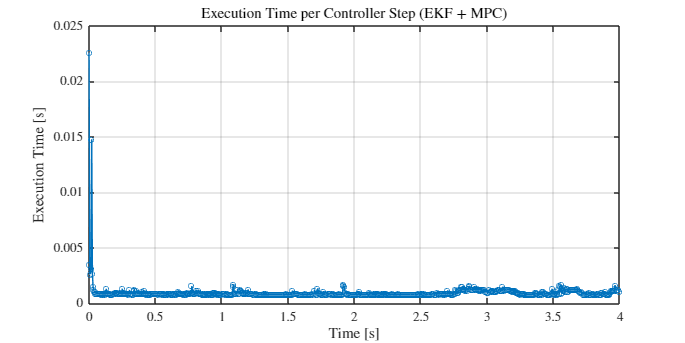



% --- Plotting ---
% Plotting can take significant time, but happens after simulation

% Plot Timing Data
figure('Position', plotPos);
plot(time_stamps_ctrl, time_log, '-o', 'MarkerSize', 4);
title('Execution Time per Controller Step (EKF + MPC)');
xlabel('Time [s]');
ylabel('Execution Time [s]');
grid on;

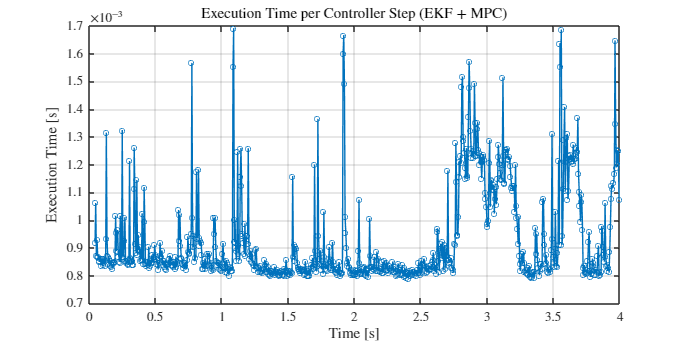


% Plot Timing Data
figure('Position', plotPos);
plot(time_stamps_ctrl(10:end), time_log(10:end), '-o', 'MarkerSize', 4);
title('Execution Time per Controller Step (EKF + MPC)');
xlabel('Time [s]');
ylabel('Execution Time [s]');
grid on;

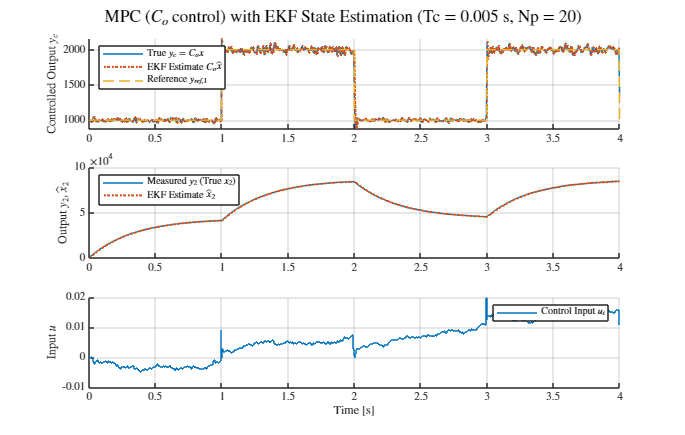




figure('Position', plotPos2);
% Plot controlled output y_c = Co * x and its reference/estimate
subplot(n_outputs_c + n_outputs, 1, 1); % Adjusted subplot count if C and Co are different
hold on;
plot((0:N_sim)*Ts_sim, (Co*x_sim(:, :))', 'DisplayName', 'True $y_c = C_o x$');

% Project EKF estimate onto controlled output
plot((0:round(N_sim/M))*Tc, (Co*xhat_sim(:, :))', ':', 'LineWidth', 1.5, 'DisplayName', 'EKF Estimate $C_o \hat{x}$');
plot((0:N_sim)*Ts_sim, y_ref_sim(1, :), '--', 'DisplayName', 'Reference $y_{ref,1}$');
ylabel('Controlled Output $y_c$');
legend('Location', 'northwest');
grid on;
hold off;

% Plot the other measured output (y2 = x2) and its estimate
subplot(n_outputs_c + n_outputs, 1, 2);
hold on;
plot((0:N_sim)*Ts_sim, y_sim(2, :), 'DisplayName', 'Measured $y_2$ (True $x_2$)'); % y_sim includes noise
% Plot true x2 for comparison
% plot((0:N_sim)*Ts_sim, x_sim(2, :), '--', 'DisplayName', 'True $x_2$');
plot((0:round(N_sim/M))*Tc, xhat_sim(2, :), ':', 'LineWidth', 1.5, 'DisplayName', 'EKF Estimate $\hat{x}_2$');
ylabel('Output $y_2, \hat{x}_2$');
legend('Location', 'northwest');
grid on;
hold off;


% Plot input
subplot(n_outputs_c + n_outputs, 1, 3);
hold on;
stairs((0:N_sim-1)*Ts_sim, u_sim, 'DisplayName', 'Control Input $u_t$');
ylabel('Input $u$');
xlabel('Time [s]');
legend('Location', 'northeast');
grid on;
hold off;

sgtitle(sprintf('MPC ($C_o$ control) with EKF State Estimation (Tc = %.3f s, Np = %d)', Tc, Np));

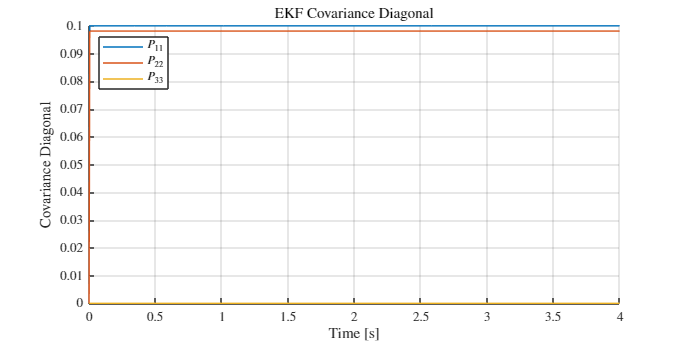


% Plot EKF Covariance Diagonal
figure('Position', plotPos);
hold on;
plot((0:round(N_sim/M))*Tc, squeeze(P_sim(1,1,:)), 'DisplayName', '$P_{11}$');
plot((0:round(N_sim/M))*Tc, squeeze(P_sim(2,2,:)), 'DisplayName', '$P_{22}$');
plot((0:round(N_sim/M))*Tc, squeeze(P_sim(3,3,:)), 'DisplayName', '$P_{33}$');
ylabel('Covariance Diagonal');
xlabel('Time [s]');
legend('Location', 'northwest');
title('EKF Covariance Diagonal');
grid on;
hold off;

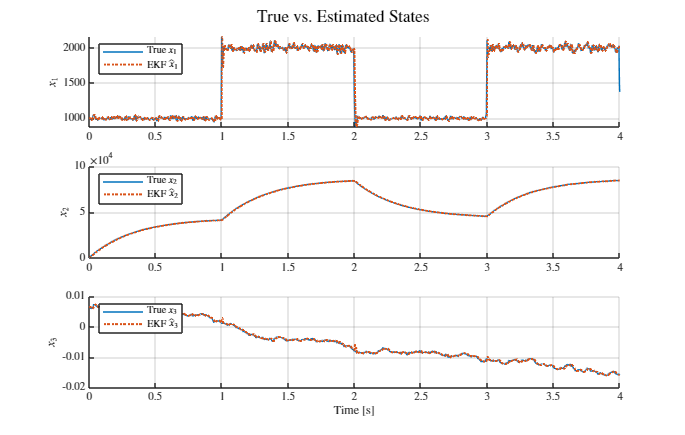



% Plot true states and estimated states
figure('Position', plotPos2);
subplot(3,1,1);
hold on;
plot((0:N_sim)*Ts_sim, x_sim(1,:), 'DisplayName', 'True $x_1$');
plot((0:round(N_sim/M))*Tc, xhat_sim(1,:), ':', 'LineWidth', 1.5, 'DisplayName', 'EKF $\hat{x}_1$');
ylabel('$x_1$'); grid on; legend('Location', 'northwest');
hold off;

subplot(3,1,2);
hold on;
plot((0:N_sim)*Ts_sim, x_sim(2,:), 'DisplayName', 'True $x_2$');
plot((0:N_sim/M)*Tc, xhat_sim(2,:), ':', 'LineWidth', 1.5, 'DisplayName', 'EKF $\hat{x}_2$');
ylabel('$x_2$'); grid on; legend('Location', 'northwest');
hold off;

subplot(3,1,3);
hold on;
plot((0:N_sim)*Ts_sim, x_sim(3,:), 'DisplayName', 'True $x_3$');
plot((0:round(N_sim/M))*Tc, xhat_sim(3,:), ':', 'LineWidth', 1.5, 'DisplayName', 'EKF $\hat{x}_3$');
ylabel('$x_3$'); xlabel('Time [s]'); grid on; legend('Location', 'northwest');
hold off;
sgtitle('True vs. Estimated States');